# Filtracja sygnałów, Filtry FIR

#### Mateusz Wójcik, 19.12.2024

Zajęcia mają na celu zapoznanie się z filtrami typu FIR (Finite Impulse Response), które są kluczowym element cyfrowego przetwarzania sygnałów, znajdującym szerokie zastosowanie w telekomunikacji, akustyce, medycynie czy systemach sterowania. W telekomunikacji filtrują szumy i zakłócenia w kanałach transmisji. W systemach radarowych poprawiają wykrywalność obiektów, a w urządzeniach mobilnych eliminują echa. Implementacja na DSP lub FPGA pozwala na ich wydajną realizację, z wykorzystaniem symetrii współczynników do redukcji liczby operacji mnożenia.

## Zad 1

Projektowanie filtru o danej transmitancji:

dla danego ciągu x:

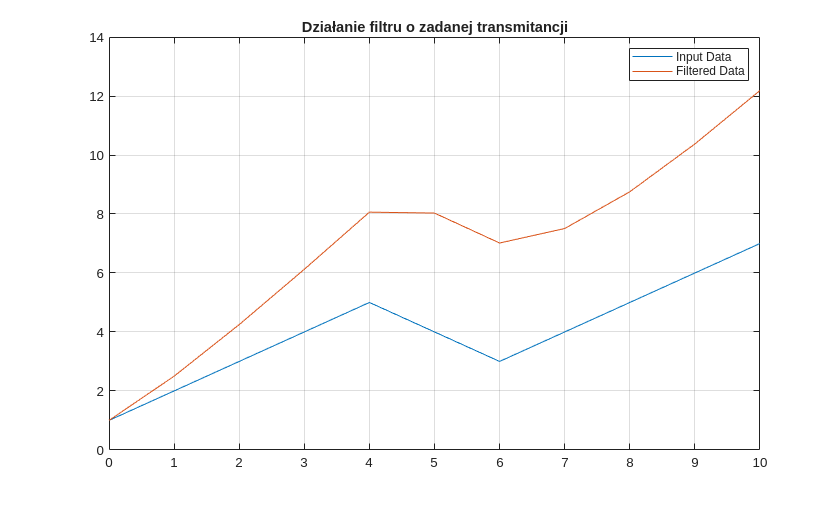

x=[1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];

b = 1;
a = [1 -0.5];
figure();
y = filter(b,a,x,[],2);

t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:), t,y(1,:))
legend('Input Data','Filtered Data');
grid on
title('Działanie filtru o zadanej transmitancji')

## Zad 2

Zaprojektować filtr o transmitancji:

 

dla danego ciągu x:

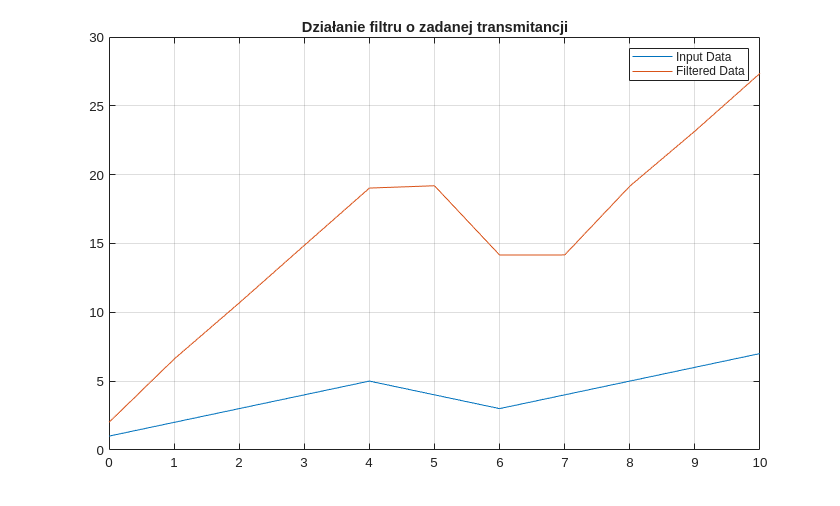

 x=[1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];

b = [2 3];
a = [1 0.2];
y = filter(b,a,x);

t = 0:length(x)-1; %indeks wektora
figure()
plot(t,x(1,:), t,y(1,:))
legend('Input Data','Filtered Data')
grid on
title('Działanie filtru o zadanej transmitancji');

## Zad 3

Projektowanie filtru dolnoprzepustowego.

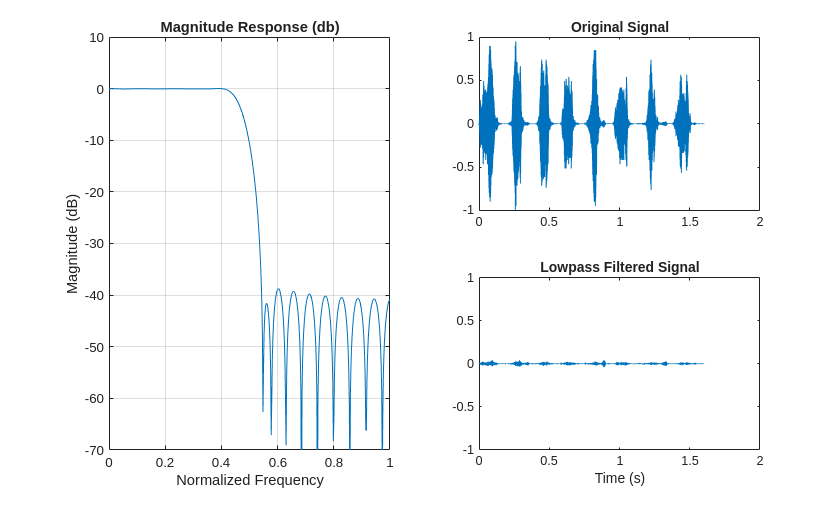

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bhi = fir1(34,0.48,'low',chebwin(35,30));
outhi = filter(bhi,1,y);

figure
subplot(2,2,[1,3])
[h,w] =freqz(bhi);
plot(w/w(end),mag2db(abs(h)))

title("Magnitude Response (db)")
ylabel("Magnitude (dB)")
xlabel("Normalized Frequency")
grid on
axis([0, 1, -70, 10])

subplot(2,2,2)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,2,4)
plot(t,outhi)
title('Lowpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)

## Zad 4

Projektowanie filtru, który będzie przepuszczać częstotliwości tłumione, natomiast tłumić będzie te przepuszczane.

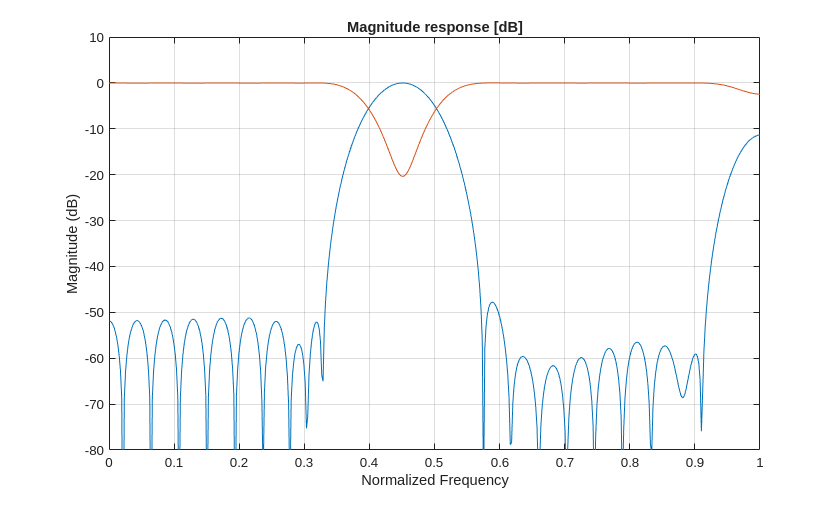

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd]);
bM2= fir1(ord,[low bnd], "DC-1");
[h1,w] = freqz(bM);
[h2,w] = freqz(bM2);
figure()
plot(w/w(end), mag2db(abs(h1)), w/w(end), mag2db(abs(h2)))
axis([0, 1, -80 10])
title("Magnitude response [dB]")
ylabel("Magnitude (dB)")
xlabel("Normalized Frequency")
grid on

## Zad 5

Projektowanie filtru, który używa okna Tukey. 

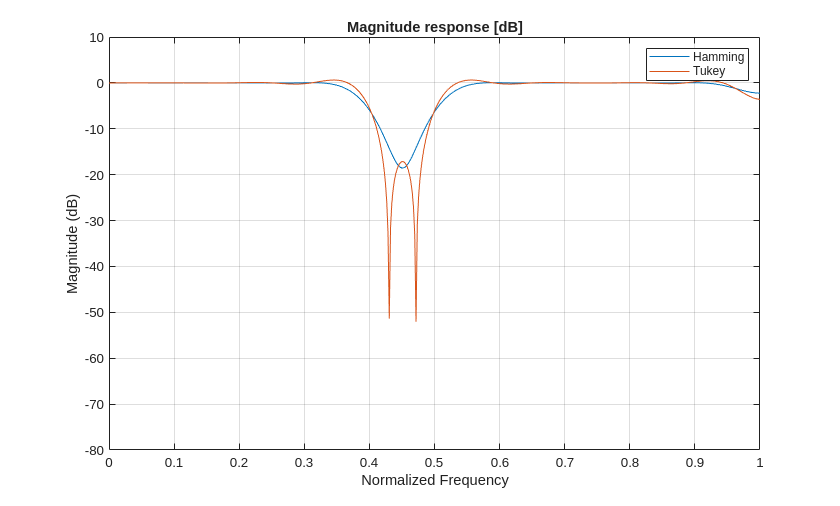

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy



bM = fir1(ord,[low bnd],'DC-1',hann(ord+1));
bT = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1));
[hH, w] = freqz(bM); %porownanie okien
[hT, w] = freqz(bT); %porownanie okien

figure()
plot(w/w(end), mag2db(abs(hH)), w/w(end), mag2db(abs(hT)))
axis([0, 1, -80 10])
title("Magnitude response [dB]")
ylabel("Magnitude (dB)")
xlabel("Normalized Frequency")
legend("Hamming", "Tukey")
grid on

Na podstawie wyników porównano okno Tukey z oknem Hamminga. Można zauważyć, że okno Hamminga w porównaniu do Tukey jest znacznie gładsze, natomiast dla częstotliwości granicznych okno Tukey ma znaczne osłabienie sygnału. 

## Zad 6

Przepuszczenie tylko składowe częstotliwości w zakresie 500 -1000 Hz i przeprowadzanie rozpoznania.

% Wczytywanie plików audio
[wiatrak_20, fs] = audioread("pliki_wav/wiatrak_20.wav");
[przekladnia_20, fs] = audioread("pliki_wav/przekladnia20.wav");
[wiatrak_21, fs] = audioread("pliki_wav/wiatrak_21.wav");
[przekladnia_21, fs] = audioread("pliki_wav/przekladnia21.wav");

[wiatrak_23, fs] = audioread("pliki_wav/wiatrak_23.wav");
[przekladnia_23, fs] = audioread("pliki_wav/przekladnia23.wav");
[wiatrak_24, fs] = audioread("pliki_wav/wiatrak_24.wav");
[przekladnia_24, fs] = audioread("pliki_wav/przekladnia24.wav");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

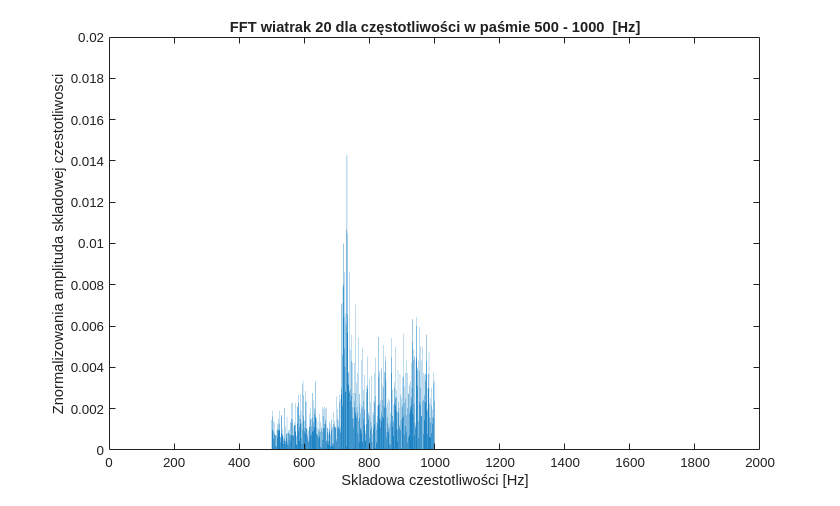

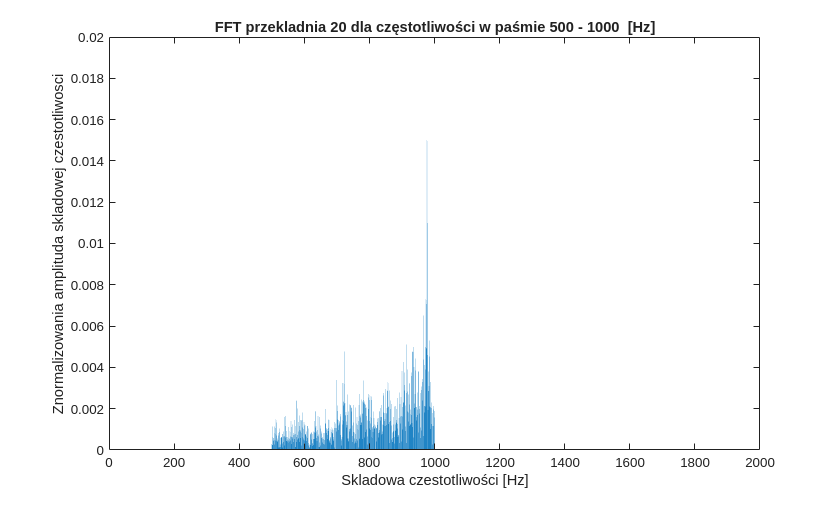

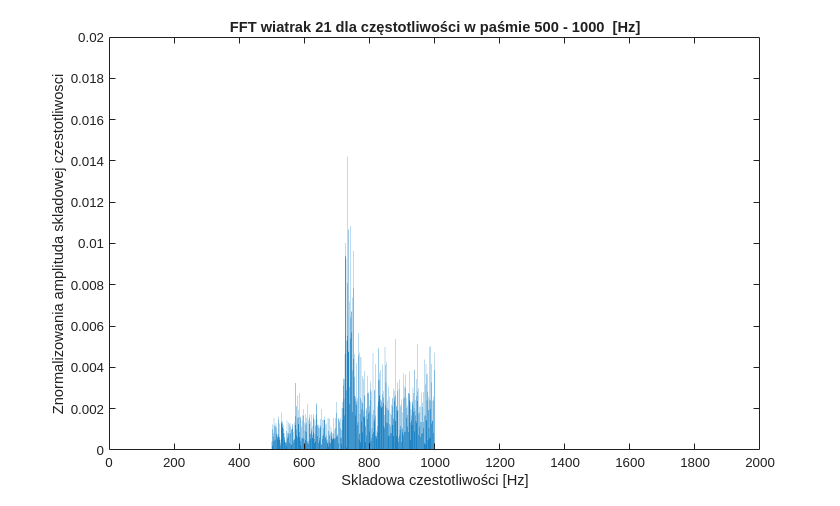

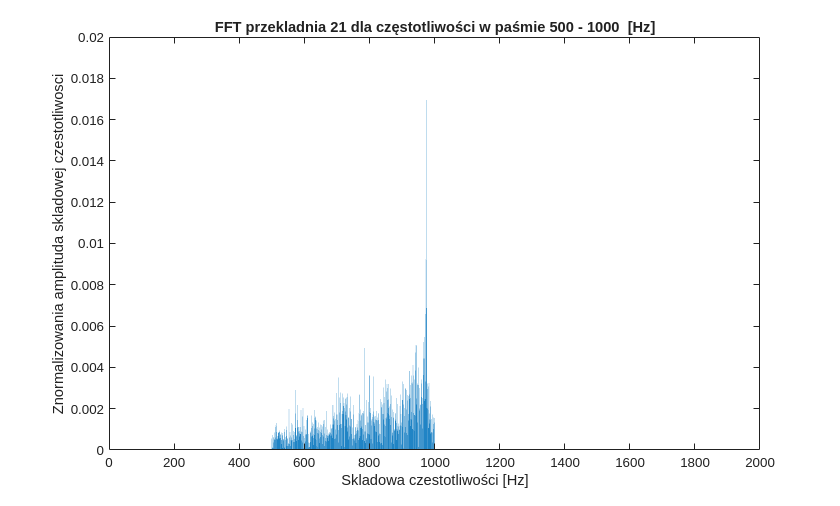

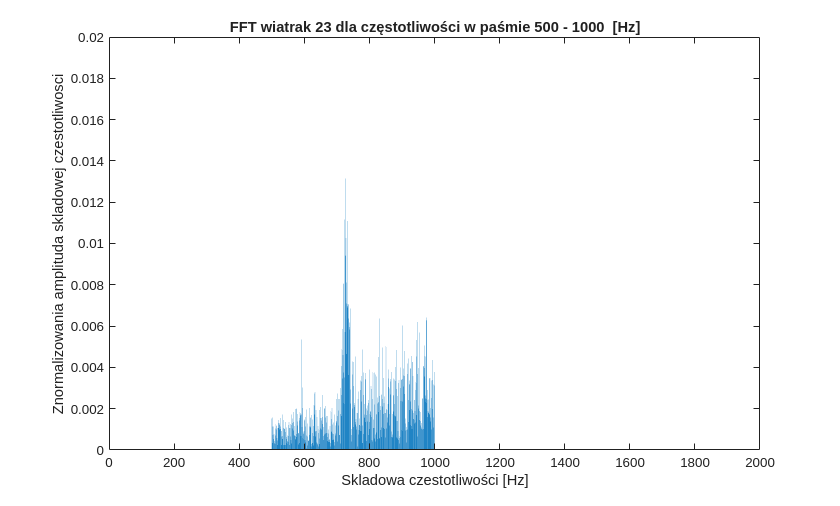

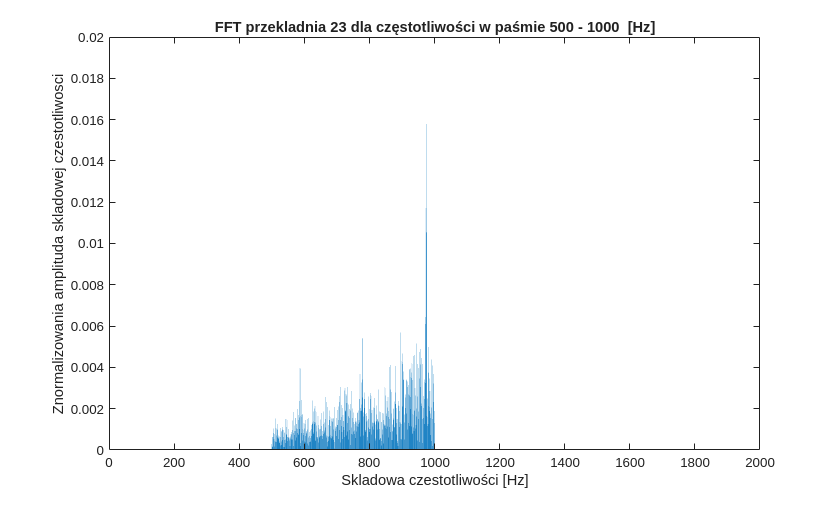

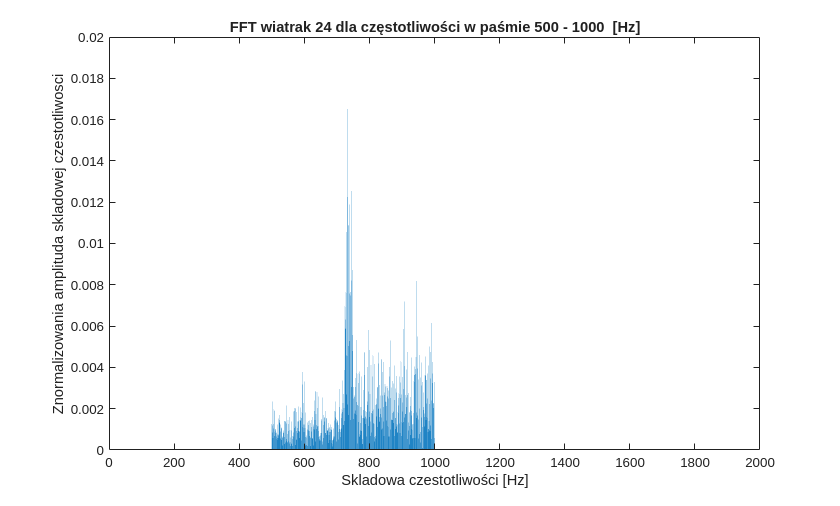

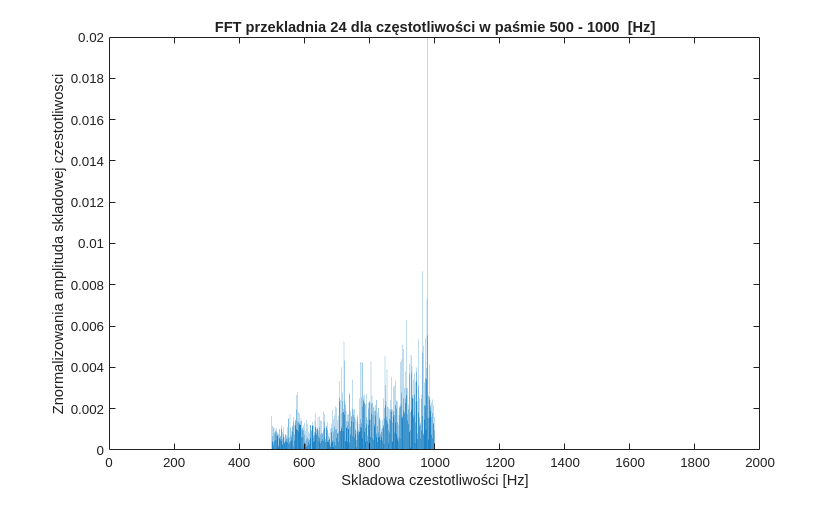

dataset = [wiatrak_20, przekladnia_20, wiatrak_21, przekladnia_21, wiatrak_23, przekladnia_23, wiatrak_24, przekladnia_24];
data_name = ["FFT_wiatrak_20", "FFT_przekladnia_20", "FFT_wiatrak_21", "FFT_przekladnia_21", "FFT_wiatrak_23", "FFT_przekladnia_23", "FFT_wiatrak_24", "FFT_przekladnia_24"];
x1=1:22050;

for n = 1:8
    data = dataset(:,n);
    max_data=max(abs(data));
    data=data/max_data;
    xfft=abs(fft(data));
    xfft=xfft/44100;
    xfft(1:499)=0;
    xfft(1001:44100)=0;

    figure()
    bar(x1, xfft(x1));
    % dodajmy osie i etykiety osi
    axis([0,2000, 0,0.02]) ;
    xlabel('Skladowa czestotliwości [Hz]');
    ylabel('Znormalizowania amplituda skladowej czestotliwosci');
    data_title = data_name(n); 
    data_title = strrep(data_title,"_", " ") + " dla częstotliwości w paśmie 500 - 1000  [Hz]";
    title(data_title)
    file_name = data_name(n) +".txt";
    fid = fopen(file_name,'w+t','n');
    fprintf(fid,'%f\n',xfft(1:22050));
    fclose(fid);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% wczytujemy probki uczące
load FFT_wiatrak_20.txt
load FFT_wiatrak_21.txt
load FFT_przekladnia_20.txt
load FFT_przekladnia_21.txt
% wczytujemy probki testowe, nieznane systemowi
load FFT_wiatrak_23.txt
load FFT_wiatrak_24.txt
load FFT_przekladnia_23.txt
load FFT_przekladnia_24.txt

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_wiatrak_23-FFT_wiatrak_20))

D = 0.6033

D=sum(abs(FFT_wiatrak_23-FFT_wiatrak_21))

D = 0.5961

D=sum(abs(FFT_wiatrak_23-FFT_przekladnia_20))

D = 0.6348

D=sum(abs(FFT_wiatrak_23-FFT_przekladnia_21))

D = 0.6130

W tym przypadku najmniejszą wartość przyjmuje różnica między wiatrakiem 23 i 21, mimo to wszystkie próbki są na zbliżonym poziomie, więc ciężko określić ich poprawność.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_wiatrak_24-FFT_wiatrak_20))

D = 0.6969

D=sum(abs(FFT_wiatrak_24-FFT_wiatrak_21))

D = 0.5753

D=sum(abs(FFT_wiatrak_24-FFT_przekladnia_20))

D = 0.6567

D=sum(abs(FFT_wiatrak_24-FFT_przekladnia_21))

D = 0.6559

Dla wiatraka 24 sytuacja uległa poprawie natomiast poziom róznicy dalej jest bardzo mały i jak można zauważyć wiatrak 20 został dopasowany do wiatraka 23 gorzej niż do przekładni.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_przekladnia_23-FFT_wiatrak_20))

D = 0.6308

D=sum(abs(FFT_przekladnia_23-FFT_wiatrak_21))

D = 0.6507

D=sum(abs(FFT_przekladnia_23-FFT_przekladnia_20))

D = 0.4742

D=sum(abs(FFT_przekladnia_23-FFT_przekladnia_21))

D = 0.4402

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_przekladnia_24-FFT_wiatrak_20))

D = 0.6610

D=sum(abs(FFT_przekladnia_24-FFT_wiatrak_21))

D = 0.6173

D=sum(abs(FFT_przekladnia_24-FFT_przekladnia_20))

D = 0.4422

D=sum(abs(FFT_przekladnia_24-FFT_przekladnia_21))

D = 0.4845

Dla przekładni sytuacja uległa znaczącej poprawie, poziom różnicy między sygnałami jest większy i z łatwością można ocenić, że przekładnie 23 i 24 zostały zidentyfikowane przez przekładnie 20 i 21.

## Zad 7

Przepuszczenie tylko składowe częstotliwości w zakresie 100 -500 Hz i przeprowadzanie rozpoznania.

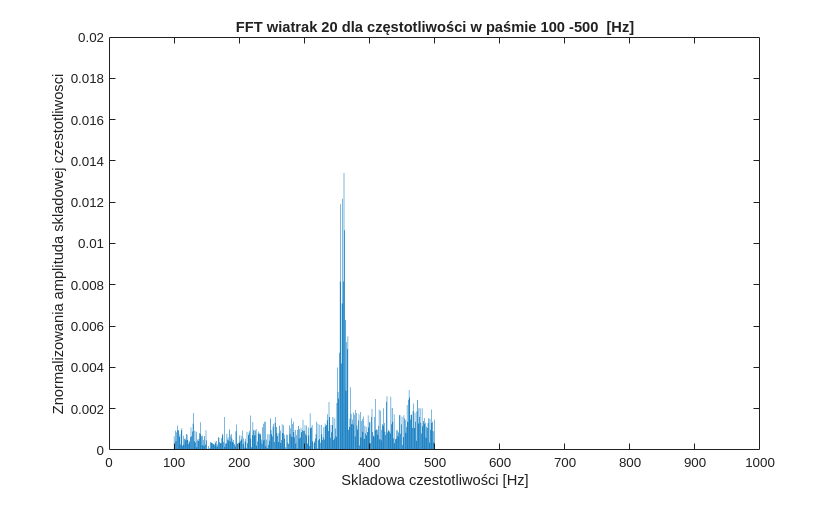

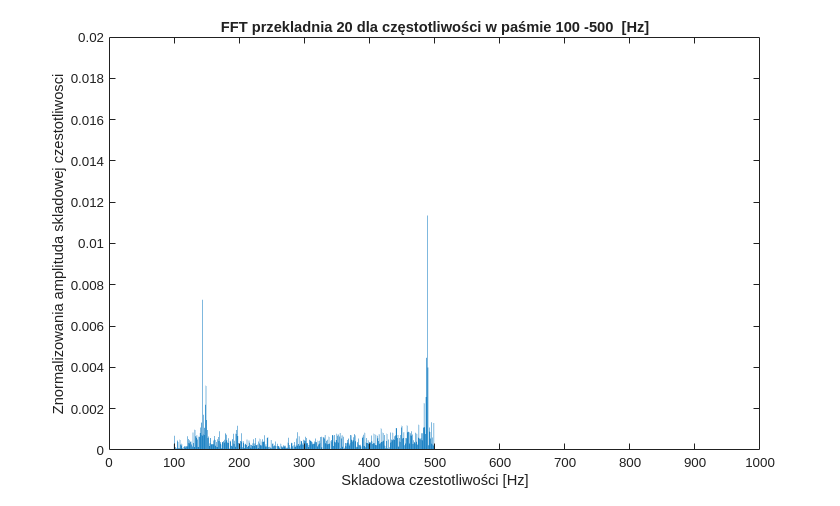

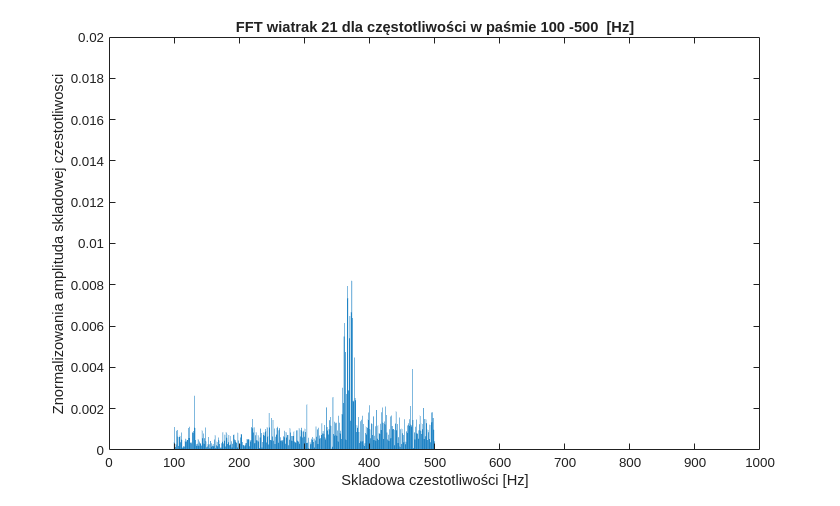

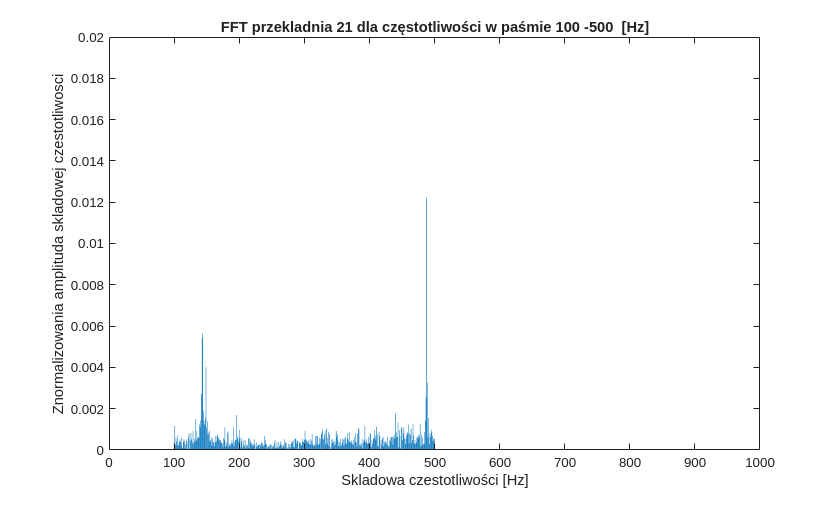

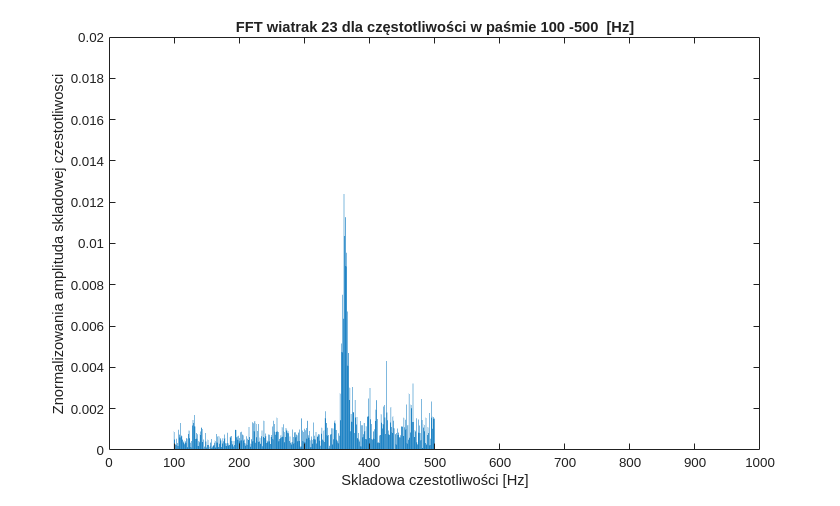

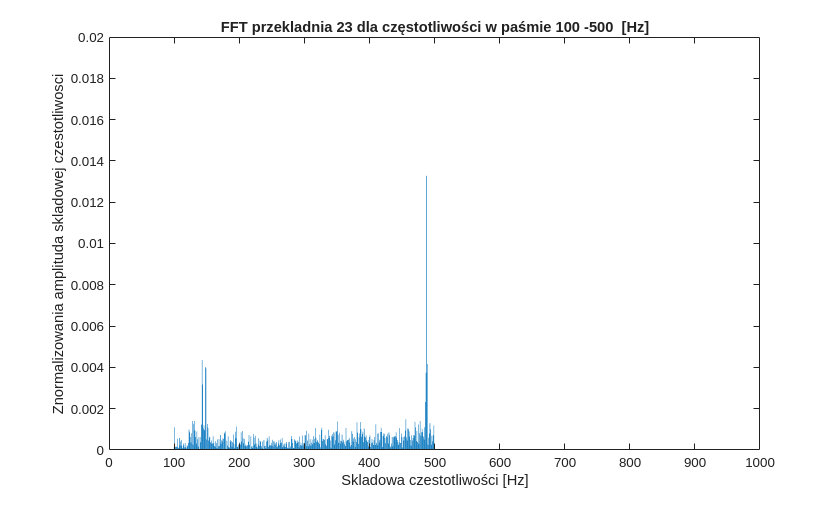

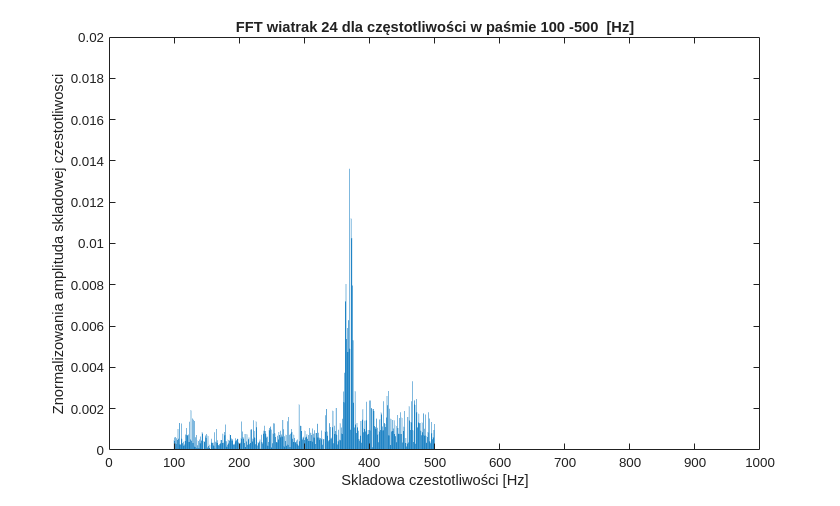

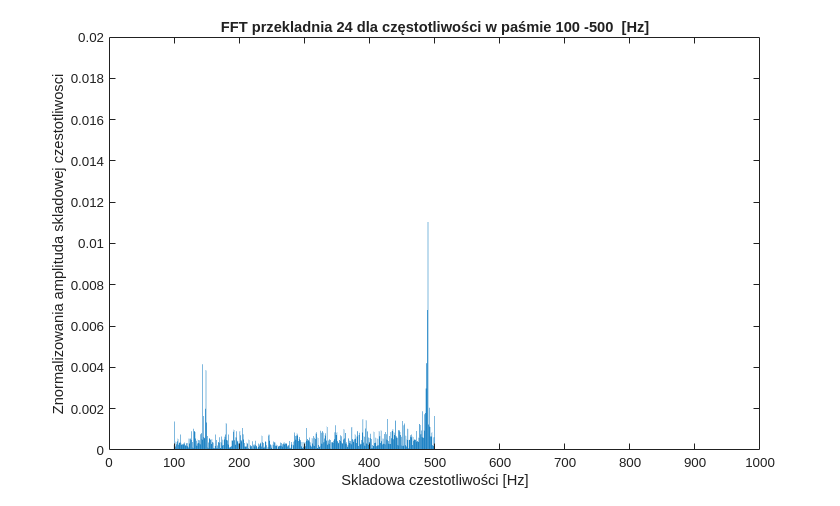


for n = 1:8
    data = dataset(:,n);
    max_data=max(abs(data));
    data=data/max_data;
    xfft=abs(fft(data));
    xfft=xfft/44100;
    xfft(1:99)=0;
    xfft(501:44100)=0;

    figure()
    bar(x1, xfft(x1));
    % dodajmy osie i etykiety osi
    axis([0,1000, 0,0.02]) ;
    xlabel('Skladowa czestotliwości [Hz]');
    ylabel('Znormalizowania amplituda skladowej czestotliwosci');
    data_title = data_name(n);
    data_title = strrep(data_title,"_", " ") + " dla częstotliwości w paśmie 100 -500  [Hz]";
    title(data_title)
    file_name = data_name(n) +".txt";
    fid = fopen(file_name,'w+t','n');
    fprintf(fid,'%f\n',xfft(1:22050));
    fclose(fid);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% wczytujemy probki uczące
load FFT_wiatrak_20.txt
load FFT_wiatrak_21.txt
load FFT_przekladnia_20.txt
load FFT_przekladnia_21.txt
% wczytujemy probki testowe, nieznane systemowi
load FFT_wiatrak_23.txt
load FFT_wiatrak_24.txt
load FFT_przekladnia_23.txt
load FFT_przekladnia_24.txt

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_wiatrak_23-FFT_wiatrak_20))

D = 0.2470

D=sum(abs(FFT_wiatrak_23-FFT_wiatrak_21)) 

D = 0.2526

D=sum(abs(FFT_wiatrak_23-FFT_przekladnia_20))

D = 0.3233

D=sum(abs(FFT_wiatrak_23-FFT_przekladnia_21))

D = 0.3282

Dla wiatraka 23 widać podobieństwo do innych wiatraków, gdyż osiągane wartości są mniejsze niż te wynikające z porównania z przekładniami.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_wiatrak_24-FFT_wiatrak_20))

D = 0.3160

D=sum(abs(FFT_wiatrak_24-FFT_wiatrak_21)) % Wartość znacząco mniejsza względem pozostałych

D = 0.2163

D=sum(abs(FFT_wiatrak_24-FFT_przekladnia_20))

D = 0.3282

D=sum(abs(FFT_wiatrak_24-FFT_przekladnia_21))

D = 0.3307

Dla wiatraka 24 widać podobieństwo do wiatraka 21, gdyż osiągnięta wartość jest mniejsza niż te wynikające z porównania z resztą.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_przekladnia_23-FFT_wiatrak_20))

D = 0.3470

D=sum(abs(FFT_przekladnia_23-FFT_wiatrak_21))

D = 0.2867

D=sum(abs(FFT_przekladnia_23-FFT_przekladnia_20))

D = 0.1390

D=sum(abs(FFT_przekladnia_23-FFT_przekladnia_21))

D = 0.1229

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D=sum(abs(FFT_przekladnia_24-FFT_wiatrak_20))

D = 0.3569

D=sum(abs(FFT_przekladnia_24-FFT_wiatrak_21))

D = 0.2876

D=sum(abs(FFT_przekladnia_24-FFT_przekladnia_20))

D = 0.1265

D=sum(abs(FFT_przekladnia_24-FFT_przekladnia_21))

D = 0.1444

Zarówno dla jednej i drugiej przekładni łatwo znaleźć podobieństwa między danymi testowanymi, a uczącymi. Na tym przykładzie widać, że odpowiednio dobrze przefiltrowane sygnały dają lepsze wyniki i do różnych zastosowań różne pasma będą się lepiej sprawdzać. Większość z z prób identyfikacji tutaj zastosowanych ma znacznie mniejszy wskaźnik błędu niż reszta w poprzednim zadaniu, a czasami znając np. częstotliwość własną obiektu jesteśmy w stanie określić jaki kawałek widma jest dla nas najbardziej interesujacy.

## Odpowiedzi na pytania

**1) Co to jest filtracja sygnałów i po co ją stosujemy?**

Filtracja sygnałów to proces przetwarzania sygnału w celu usunięcia niepożądanych składowych, takich jak szumy, zakłócenia lub określone pasma częstotliwości. Wyróżnia się filtry dolnoprzepustowe, górnoprzepustowe, pasmowoprzepustowe i pasmowozaporowe, ze względu na przepuszczane pasma. Natomiast ze względu na implementację filtrów cyfrowych mamy filtry typu FIR i IIR. Filtrację stosuje się w telekomunikacji do oczyszczania sygnału z szumów, w systemach audio do korekcji dźwięku, a w przetwarzaniu obrazów do redukcji zakłóceń. W systemach sterowania filtry poprawiają stabilność układów oraz umożliwia lepszą interpretację i analizę sygnałów, co jest kluczowe w urządzeniach medycznych, radarach i przemyśle kosmicznym.

**2) Co to jest filtr FIR i czym się charakteryzuje?**

Filtr FIR (Finite Impulse Response) to rodzaj filtra cyfrowego o skończonej odpowiedzi impulsowej. Jego wyjście zależy jedynie od aktualnych i przeszłych wartości sygnału wejściowego, bez sprzężenia zwrotnego. Współczynniki filtra FIR są stałe, a odpowiedź impulsowa zanika po określonej liczbie próbek. Filtry FIR zapewniają liniową fazę, co pozwala na brak fazowego zniekształcenie sygnału, co jest istotne w przetwarzaniu obrazów, dźwięku i sygnałów medycznych. Są one stabilne, ponieważ nie zawierają sprzężenia zwrotnego. Ich implementacja jest prostsza od filtrów IIR, ale może wymagać większej liczby operacji, zwłaszcza w przypadku filtrów o ostrych zboczach.

**3) W jaki sposób projektujemy filtry FIR?**

Projektowanie filtrów FIR obejmuje określenie wymagań częstotliwościowych (np. pasma przepustowego i tłumienia), a następnie obliczenie współczynników filtra. Popularne metody projektowania to metoda okien, metoda Remeza i metoda oparta na funkcjach aproksymacyjnych. Metoda okien polega na zaprojektowaniu idealnego filtra i ograniczeniu jego odpowiedzi impulsowej przez okno (np. Hanninga, Hamminga). Metoda Remeza pozwala na bardziej precyzyjną kontrolę charakterystyk filtra. Obliczone współczynniki można implementować na procesorach DSP, FPGA lub w oprogramowaniu. Dla optymalizacji liczby operacji mnożenia stosuje się symetrię współczynników i algorytmy MCM (multiple-constant multiplication).

**4) Do czego służą okna?**

Okna w przetwarzaniu sygnałów to funkcje matematyczne używane do ograniczania długości sygnału lub odpowiedzi impulsowej filtra. Stosuje się je, by zminimalizować zjawisko "przecieku" widmowego (ang. spectral leakage) podczas analizy częstotliwościowej za pomocą FFT lub do projektowania filtrów FIR. Okno "wygładza" ostre krawędzie sygnału, zmniejszając niepożądane składowe częstotliwości. W projektowaniu filtrów FIR okno ogranicza nieskończoną odpowiedź impulsową filtra idealnego do skończonej liczby próbek. Typowe okna to okna Hamminga, Hanninga, Blackmana i prostokątne. Wybór okna zależy od kompromisu między szerokością głównej loby a tłumieniem bocznych lob widma.

## Wnioski

Na laboratorium zapoznano się z podstawami tworzenia filtrów FIR w środowisku Maltab. Filtracja sygnałów jest kluczowym procesem umożliwiającym usuwanie szumów, zakłóceń oraz niepożądanych pasm częstotliwości, co poprawia jakość sygnału w telekomunikacji, akustyce, systemach medycznych i obrazowaniu. Filtry FIR (Finite Impulse Response) wyróżniają się stabilnością, liniową fazą oraz skończoną odpowiedzią impulsową, co pozwala na precyzyjne kształtowanie charakterystyki częstotliwościowej bez zniekształceń sygnału. Metody projektowania filtrów FIR obejmują metodę okien oraz metodę Remeza. Metoda okien, choć prostsza, oferuje mniejszą kontrolę nad charakterystyką filtra, podczas gdy metoda Remeza umożliwia precyzyjne dopasowanie parametrów częstotliwościowych. Okna, takie jak Hamming, Hanning czy Blackman, ograniczają odpowiedź impulsową filtra i minimalizują przecieki widmowe w analizie FFT. Filtry FIR, dzięki swoim właściwościom, są szeroko stosowane w systemach przetwarzania dźwięku, obrazu i sygnałów biomedycznych, zapewniając wysoką jakość filtracji.